# CORRECCION PRIMER PARCIAL TAC

Julian Cortes -1803147

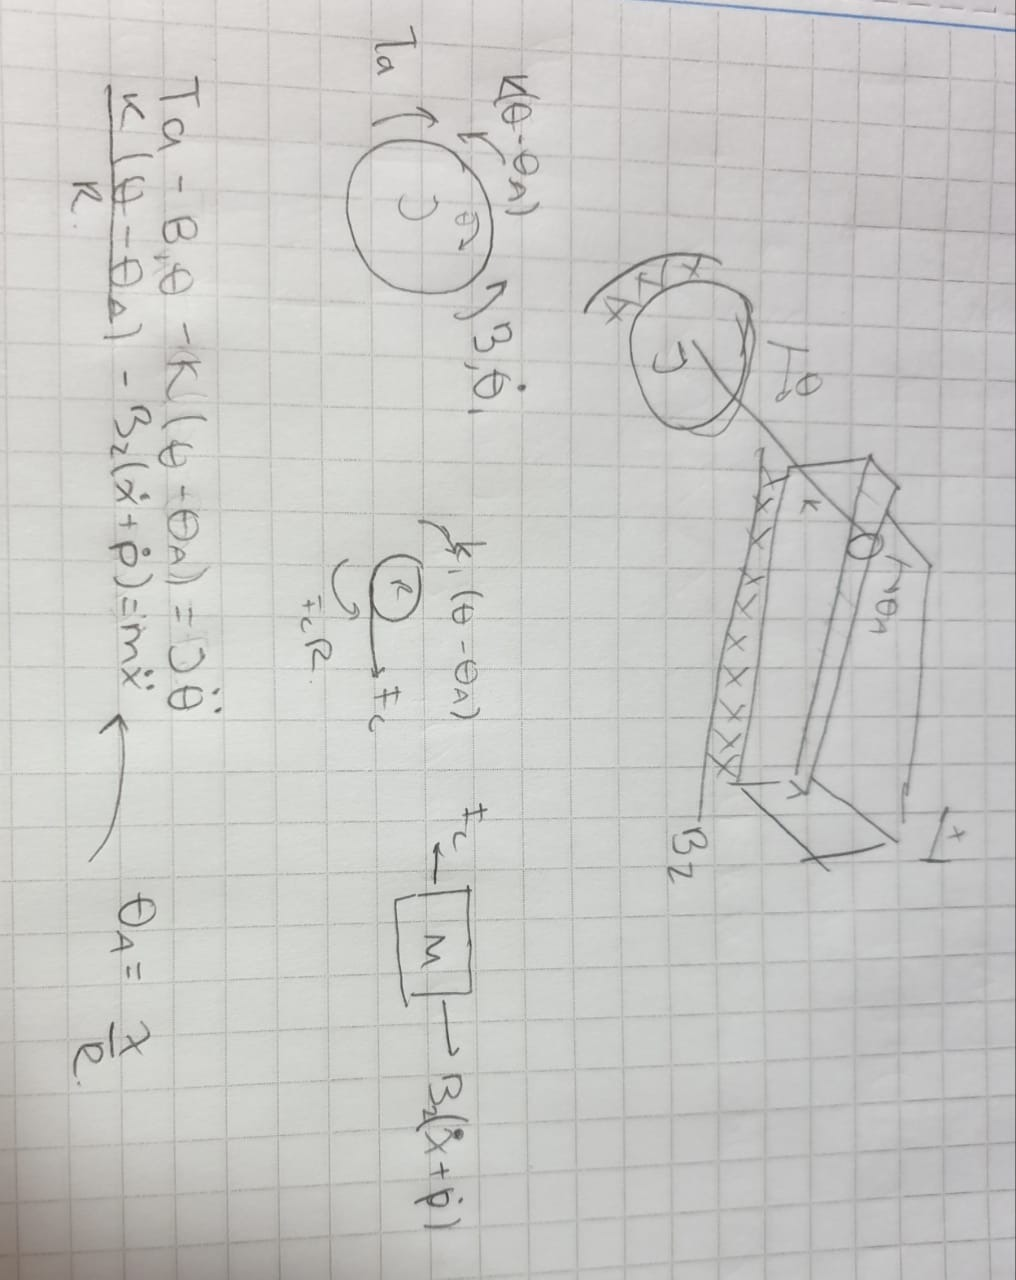

Se reliza el modeleo para hallar el espacio de estados del sistema mecanico

sympref('FloatingPointOutput',true);
format shortE;
digitsOld=digits(2);

syms J M ta b1 b2 th p pp x v r w k
wp=(1/J)*(ta-b1*w-k*(th-((x+p)/r)))

$$wp = -\frac{k\,\left(\mathrm{th}-\frac{p+x}{r}\right)-\mathrm{ta}+b_{1}\,w}{J}$$

vp=(1/M)*(-b2*(v+pp)+(k/r)*(th-((x+p)/r)))

$$vp = -\frac{b_{2}\,\left(\mathrm{pp}+v\right)-\frac{k\,\left(\mathrm{th}-\frac{p+x}{r}\right)}{r}}{M}$$

xp=v

$$xp = v$$

thp=w

$$thp = w$$


xe=[w,v,x,th]

$$xe = \left(\begin{array}{cccc} w & v & x & \mathrm{th} \end{array}\right)$$

y=x

$$y = x$$


A=jacobian([wp,vp,xp,thp],xe)

$$A = \left(\begin{array}{cccc} -\frac{b_{1}}{J} & 0 & \frac{k}{J\,r} & -\frac{k}{J}\\ 0 & -\frac{b_{2}}{M} & -\frac{k}{M\,r^{2}} & \frac{k}{M\,r}\\ 0 & 1 & 0 & 0\\ 1 & 0 & 0 & 0 \end{array}\right)$$

B=jacobian([wp,vp,xp,thp],ta)

$$B = \left(\begin{array}{c} \frac{1}{J}\\ 0\\ 0\\ 0 \end{array}\right)$$

C=jacobian(y,xe)

$$C = \left(\begin{array}{cccc} 0 & 0 & 1 & 0 \end{array}\right)$$

D=jacobian(y,ta)

$$D = 0$$

E=jacobian([wp,vp,xp,thp],p)

$$E = \left(\begin{array}{c} \frac{k}{J\,r}\\ -\frac{k}{M\,r^{2}}\\ 0\\ 0 \end{array}\right)$$

F=jacobian([wp,vp,xp,thp],pp)

$$F = \left(\begin{array}{c} 0\\ -\frac{b_{2}}{M}\\ 0\\ 0 \end{array}\right)$$

Una vez se tiene el espacio de estados del sistema hacemos la representacion con las constantes para tener ya numerico el sistema

M=10%Kg

M =     10


b1=20%Nm/s

b1 =     20


b2=10%Kg/s

b2 =     10


k=10%Nm

k =     10


r=0.1%m

r =    1.0000e-01


J=20%Kgm^2

J =     20



A=double(eval(A))

A =   -1.0000e+00            0   5.0000e+00  -5.0000e-01
            0  -1.0000e+00  -1.0000e+02   1.0000e+01
            0   1.0000e+00            0            0
   1.0000e+00            0            0            0


B=double(eval(B))

B =    5.0000e-02
            0
            0
            0


C=double(eval(C))

C =      0     0     1     0


D=double(eval(D))

D =      0


E=double(eval(E))

E =    5.0000e+00
  -1.0000e+02
            0
            0


F=double(eval(F))

F =      0
    -1
     0
     0


syms s
ft=C*(inv(eye(4)*s-A))*B+D

$$ft = \frac{1}{2\,s^{4}+4\,s^{3}+203\,s^{2}+201\,s}$$

Hallamos la funcion de tranferencia del sistema, y su respuetsa al escalon

[num,den]=ss2tf(A,B,C,D)

num =             0            0            0            0   5.0000e-01


den =    1.0000e+00   2.0000e+00   1.0150e+02   1.0050e+02   1.2582e-14


den(5)=0.0

den =    1.0000e+00   2.0000e+00   1.0150e+02   1.0050e+02            0


ft=tf(num,den)


ft =
 
                 0.5
  ---------------------------------
  s^4 + 2 s^3 + 101.5 s^2 + 100.5 s
 
Continuous-time transfer function.



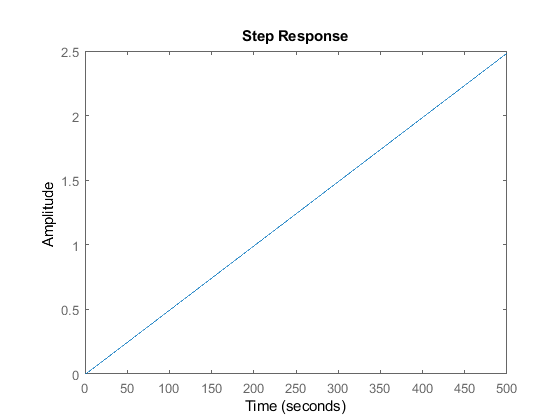

step(ft)

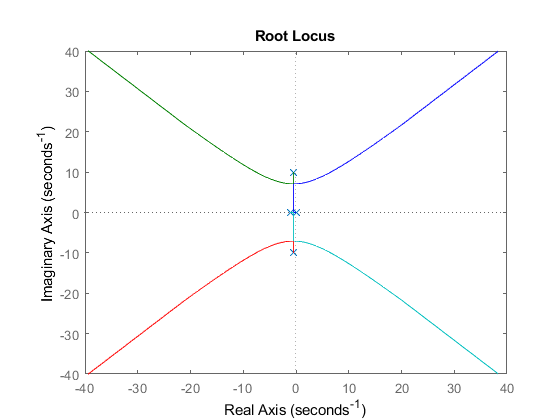

rlocus(ft)

roots(den)
dena=[den(1),den(2),den(3),den(4)]

dena =    1.0000e+00   2.0000e+00   1.0150e+02   1.0050e+02


fta=tf(num,dena)


fta =
 
               0.5
  -----------------------------
  s^3 + 2 s^2 + 101.5 s + 100.5
 
Continuous-time transfer function.



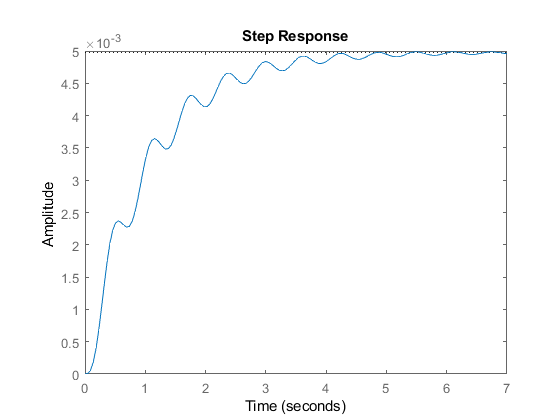

step(fta)

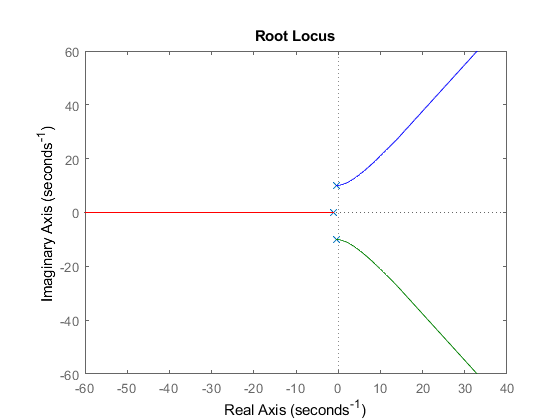

rlocus(fta)

#### Servosistema y observador

Se procede a hallar le servosistema, para esto hacemos uso de el metodo de Ackerman y el mismo para el observador de estados. 

ts=0.25%s

ts =    2.5000e-01


zeta=0.6

zeta =    6.0000e-01


wn=4/(zeta*ts)

wn =    2.6667e+01


syms s
n=2

n =      2


pol=[1 2*zeta*wn wn^2]

pol =    1.0000e+00   3.2000e+01   7.1111e+02


pol=conv(pol,[1 5*zeta*wn])

pol =    1.0000e+00   1.1200e+02   3.2711e+03   5.6889e+04


pol=conv(pol,[1 5*zeta*wn])

pol =    1.0000e+00   1.9200e+02   1.2231e+04   3.1858e+05   4.5511e+06


El observador de estados por Ackerman

tsO=ts/10

tsO =    2.5000e-02


zetaO=0.9

zetaO =    9.0000e-01


wnO=4/(zetaO*tsO)

wnO =    1.7778e+02


polObs=[1 2*zeta*wn wn^2]

polObs =    1.0000e+00   3.2000e+01   7.1111e+02


polObs=conv(polObs,[1 5*zetaO*tsO])

polObs =    1.0000e+00   3.2112e+01   7.1471e+02   8.0000e+01


polObs=conv(polObs,[1 5*zetaO*tsO])

polObs =    1.0000e+00   3.2225e+01   7.1832e+02   1.6041e+02   9.0000e+00


Ke=ObsAcker(A,B,C,polObs)

Ke =    2.5751e+01
   5.5637e+02
   3.0225e+01
  -5.4181e+01


El servosistema :

pol=conv(pol,[1 5*zeta*wn])

pol =    1.0000e+00   2.7200e+02   2.7591e+04   1.2971e+06   3.0037e+07   3.6409e+08


Aempaq=[A,zeros(4,1);-C,0]

Aempaq =   -1.0000e+00            0   5.0000e+00  -5.0000e-01            0
            0  -1.0000e+00  -1.0000e+02   1.0000e+01            0
            0   1.0000e+00            0            0            0
   1.0000e+00            0            0            0            0
            0            0  -1.0000e+00            0            0


Bempaq=[B;0]

Bempaq =    5.0000e-02
            0
            0
            0
            0


K=acker(Aempaq,Bempaq,roots(pol))

K =    5.4000e+03   2.4855e+06   5.4631e+07   5.4439e+05  -7.2818e+08


Al ver la salida del sistema sin perturbaciones tenemos:

Ahora si hacemos lo mismo con perturbaciones tenemos:

La salida del sistema con perturbaciones vemos que es marginalmente estable, por lo que aunque el sistema sea de orden 4, no es tan robusto frente a la perturbacion.

#### PID PARA EL SISTEMA

%el sistema necesita un PID^3
syms kd1 ki kd2 kd3 kp s

pol=[1 2*zeta*wn wn^2]

pol =    1.0000e+00   3.2000e+01   7.1111e+02


pol=conv(pol,[1 5*zeta*wn])

pol =    1.0000e+00   1.1200e+02   3.2711e+03   5.6889e+04


pol=conv(pol,[1 5*zeta*wn])

pol =    1.0000e+00   1.9200e+02   1.2231e+04   3.1858e+05   4.5511e+06


pol=conv(pol,[1 5*zeta*wn])

pol =    1.0000e+00   2.7200e+02   2.7591e+04   1.2971e+06   3.0037e+07   3.6409e+08


ftSim=0.5/((s^4+2*s^3+101.5*s^2+100.5*s))

$$ftSim = \frac{0.5000}{s^{4}+2\,s^{3}+101.5000\,s^{2}+100.5000\,s}$$

PID=collect(kp+ki/s+kd1*s+kd2*s^2+kd3*s^3,s)

$$PID = \frac{{\mathrm{kd}}_{3}\,s^{4}+{\mathrm{kd}}_{2}\,s^{3}+{\mathrm{kd}}_{1}\,s^{2}+\mathrm{kp}\,s+\mathrm{ki}}{s}$$

[A1,A2]=numden(ftSim)

$$A1 = 1$$

$$A2 = 2\,s^{4}+4\,s^{3}+203\,s^{2}+201\,s$$

[B1,B2]=numden(PID)

$$B1 = {\mathrm{kd}}_{3}\,s^{4}+{\mathrm{kd}}_{2}\,s^{3}+{\mathrm{kd}}_{1}\,s^{2}+\mathrm{kp}\,s+\mathrm{ki}$$

$$B2 = s$$

Gs=collect(A2*B2+A1*B1,s)

$$Gs = 2\,s^{5}+\left({\mathrm{kd}}_{3}+4\right)\,s^{4}+\left({\mathrm{kd}}_{2}+203\right)\,s^{3}+\left({\mathrm{kd}}_{1}+201\right)\,s^{2}+\mathrm{kp}\,s+\mathrm{ki}$$

Gs=fliplr(coeffs(Gs,s))/2

$$Gs = \left(\begin{array}{cccccc} 1 & 0.5000\,{\mathrm{kd}}_{3}+2 & 0.5000\,{\mathrm{kd}}_{2}+101.5000 & 0.5000\,{\mathrm{kd}}_{1}+100.5000 & 0.5000\,\mathrm{kp} & 0.5000\,\mathrm{ki} \end{array}\right)$$

Gs=transpose(Gs)

$$Gs = \left(\begin{array}{c} 1\\ 0.5000\,{\mathrm{kd}}_{3}+2\\ 0.5000\,{\mathrm{kd}}_{2}+101.5000\\ 0.5000\,{\mathrm{kd}}_{1}+100.5000\\ 0.5000\,\mathrm{kp}\\ 0.5000\,\mathrm{ki} \end{array}\right)$$

pola=transpose(pol)

pola =    1.0000e+00
   2.7200e+02
   2.7591e+04
   1.2971e+06
   3.0037e+07
   3.6409e+08


vars=[ki,kp,kd1,kd2,kd3]

$$vars = \left(\begin{array}{ccccc} \mathrm{ki} & \mathrm{kp} & {\mathrm{kd}}_{1} & {\mathrm{kd}}_{2} & {\mathrm{kd}}_{3} \end{array}\right)$$

eqn=pola==Gs

$$eqn = \left(\begin{array}{c} 1=1\\ 272=0.5000\,{\mathrm{kd}}_{3}+2\\ 2.7591e+04=0.5000\,{\mathrm{kd}}_{2}+101.5000\\ 1.2971e+06=0.5000\,{\mathrm{kd}}_{1}+100.5000\\ 3.0037e+07=0.5000\,\mathrm{kp}\\ 3.6409e+08=0.5000\,\mathrm{ki} \end{array}\right)$$

[ki,kp,kd1,kd2,kd3]=solve(pola==Gs,vars)

$$ki = 7.2818e+08$$

$$kp = 6.0075e+07$$

$$kd1 = 2.5939e+06$$

$$kd2 = 5.4979e+04$$

$$kd3 = 540$$

ki=double(ki)

ki =    728180000


kp=double(kp)

kp =     60075000


kd1=double(kd1)

kd1 =      2593900


kd2=double(kd2)

kd2 =        54979


kd3=double(kd3)

kd3 =    540


% Discreto FOH
KP=338.79   

KP =    3.3879e+02


KI=64.92    

KI =    6.4920e+01


KD=383.35

KD =    3.8335e+02


Ti=KP/KI

Ti =    5.2186e+00


Td=KD/KP

Td =    1.1315e+00


frec=30

frec =     30


tm=(2*pi)/(frec*wn)

tm =    7.8540e-03


q0=KP*(1+(tm/Ti)+(Td/tm))

q0 =    4.9149e+04


q1=KP*(-1-2*(Td/tm))

q1 =   -9.7958e+04


q2=KP*(Td/tm)

q2 =    4.8810e+04



ft1 =
 
  s
 
Continuous-time transfer function.




ftd =
 
  254.6 z - 254.6
  ---------------
       z + 1
 
Sample time: 0.007854 seconds
Discrete-time transfer function.

